## Shared variables

trimeshmg = @(v,f) trimesh(f, v(:,1), v(:,2), v(:,3), v(:,end), 'FaceColor', 'flat', 'FaceVertexCData',calcFaceArea(v,f),'EdgeColor',[.5,.5,.5],'LineWidth',0.1);
ff = @() cellfun(@feval, {@(x) axis('image'), @(x) view(3)}, {[],[]}, 'Uni', 0); % format figure
figuremax = @() figure('Units', 'normalized', 'Position', [0 0 1 1]);

## Two meshes with the same number of faces/verts and same area per face

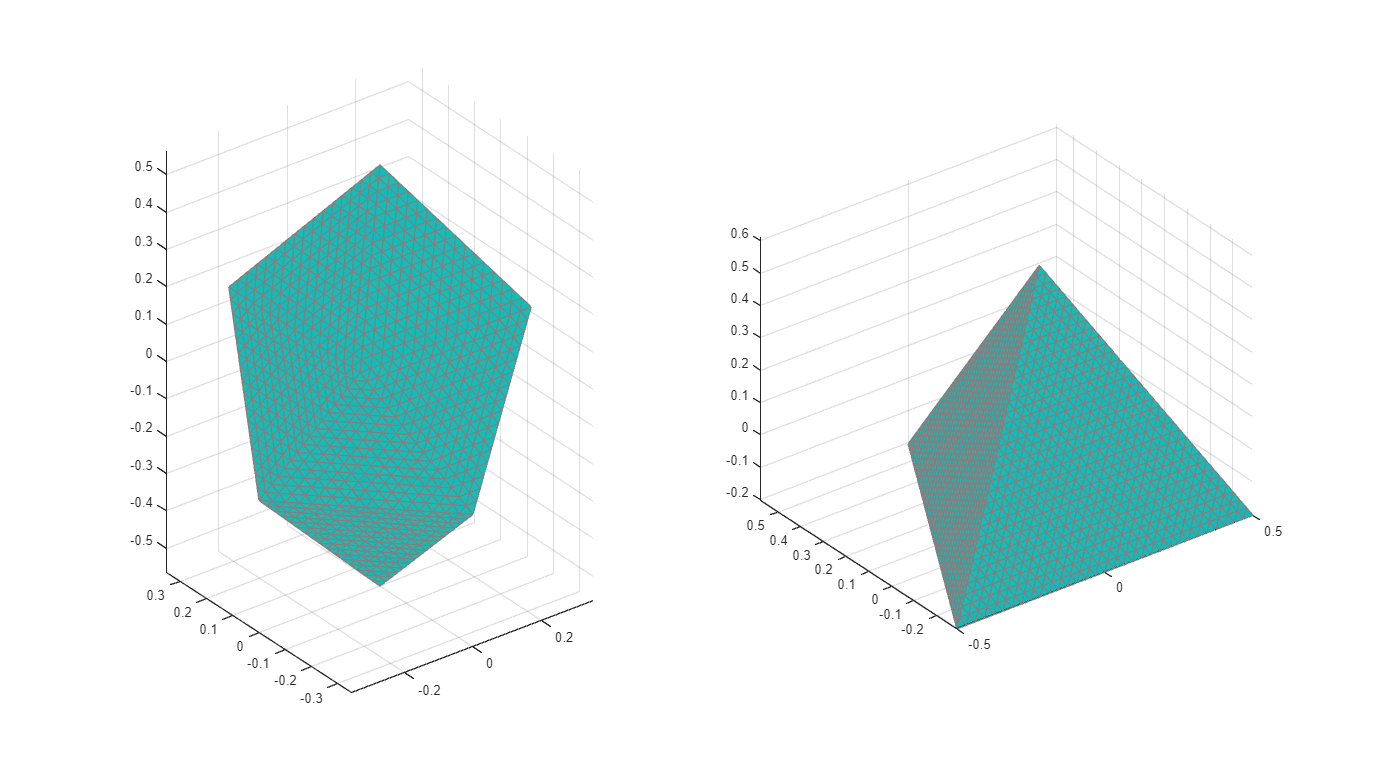

figuremax(); 

[verts, faces] = equilateralMesh(16);
verts = verts/2; % normalize surface area
[verts, faces] = increasePatch(verts, faces, 4);
nexttile; trimeshmg(verts, faces); ff();
% nexttile; bar(calcFaceArea(verts, faces));

[verts, faces] = equilateralMesh(4);
[verts, faces] = increasePatch(verts, faces, 5);
nexttile; trimeshmg(verts, faces); ff();

% nexttile; bar(calcFaceArea(verts, faces));

## Create a surface and repeatedly subdivide it; augment once during that process

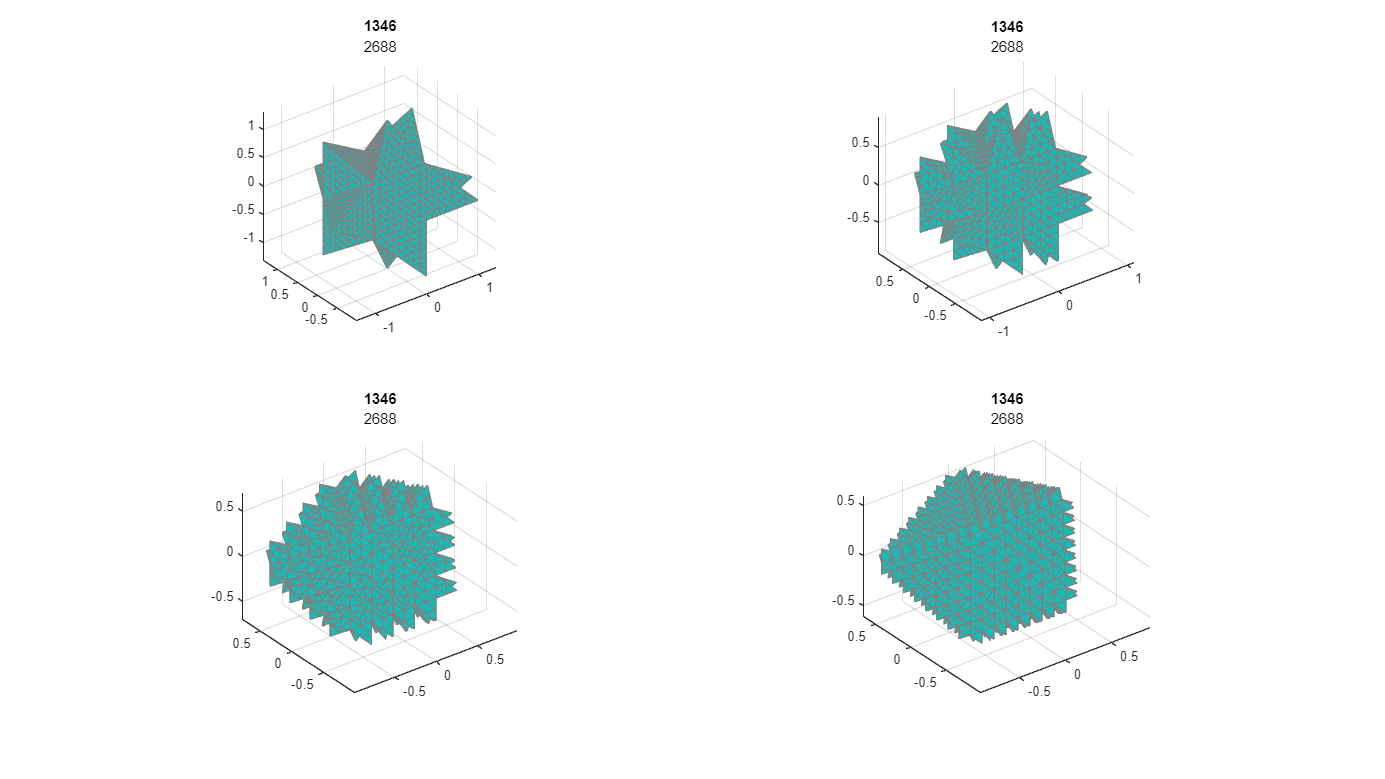

nSurfaces = 4;

[v,f] = equilateralMesh(14);
verts = arrayfun(@(x) v, 1:nSurfaces, 'Uni', 0);
faces = arrayfun(@(x) f, 1:nSurfaces, 'Uni', 0);

for ii = 1:nSurfaces
    for jj = 1:nSurfaces
        if ii == jj; [verts{jj}, faces{jj}] = augmentFace(verts{jj}, faces{jj});
        else; [verts{jj}, faces{jj}] = increasePatch(verts{jj}, faces{jj}); end
    end
end

figuremax();
for ii = 1:nSurfaces
    nexttile;
    trimeshmg(verts{ii}, faces{ii}); ff();
    title(string(height(verts{ii})));
    subtitle(string(height(faces{ii})));

    % nexttile; bar(calcFaceArea(verts{ii}, faces{ii}));
end

## Create a surface and repeatedly subdivide it; augment randomly at the end

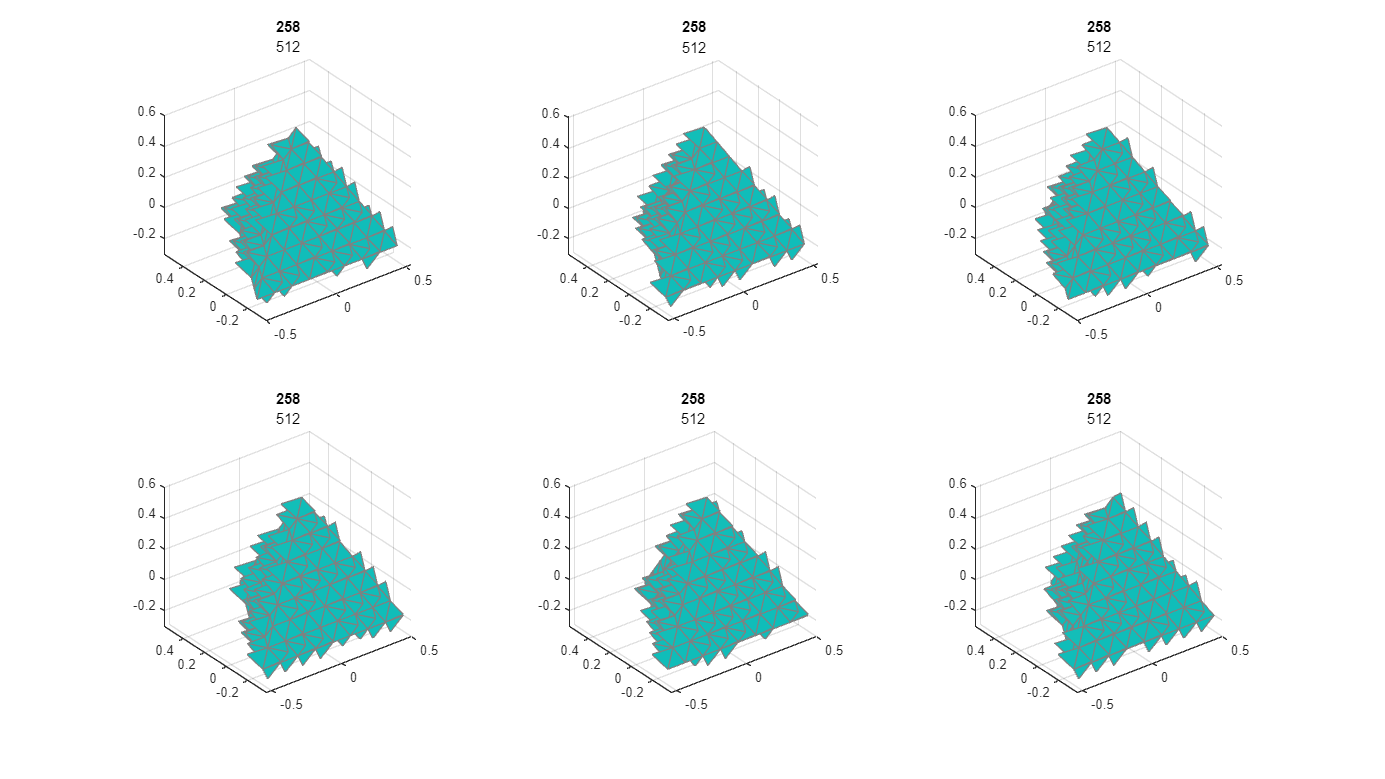

nDivisions = 3;
nSurfaces = 6;

[v,f] = equilateralMesh(4);
for ii = 1:nDivisions
    [v,f] = increasePatch(v,f);
end

for ii = 1:nSurfaces
    rng(ii);
    faceIds = randperm(height(f), height(f)/2); % augment half the faces
    [verts{ii}, faces{ii}] = augmentFace(v, f, faceIds); 
end

figuremax();
for ii = 1:nSurfaces
    nexttile;
    trimeshmg(verts{ii}, faces{ii}); ff();
    title(string(height(verts{ii})));
    subtitle(string(height(faces{ii})));

    % nexttile; bar(calcFaceArea(verts{ii}, faces{ii}));
end

## Test on non-equilateral triangles; note that new faces won't have same area

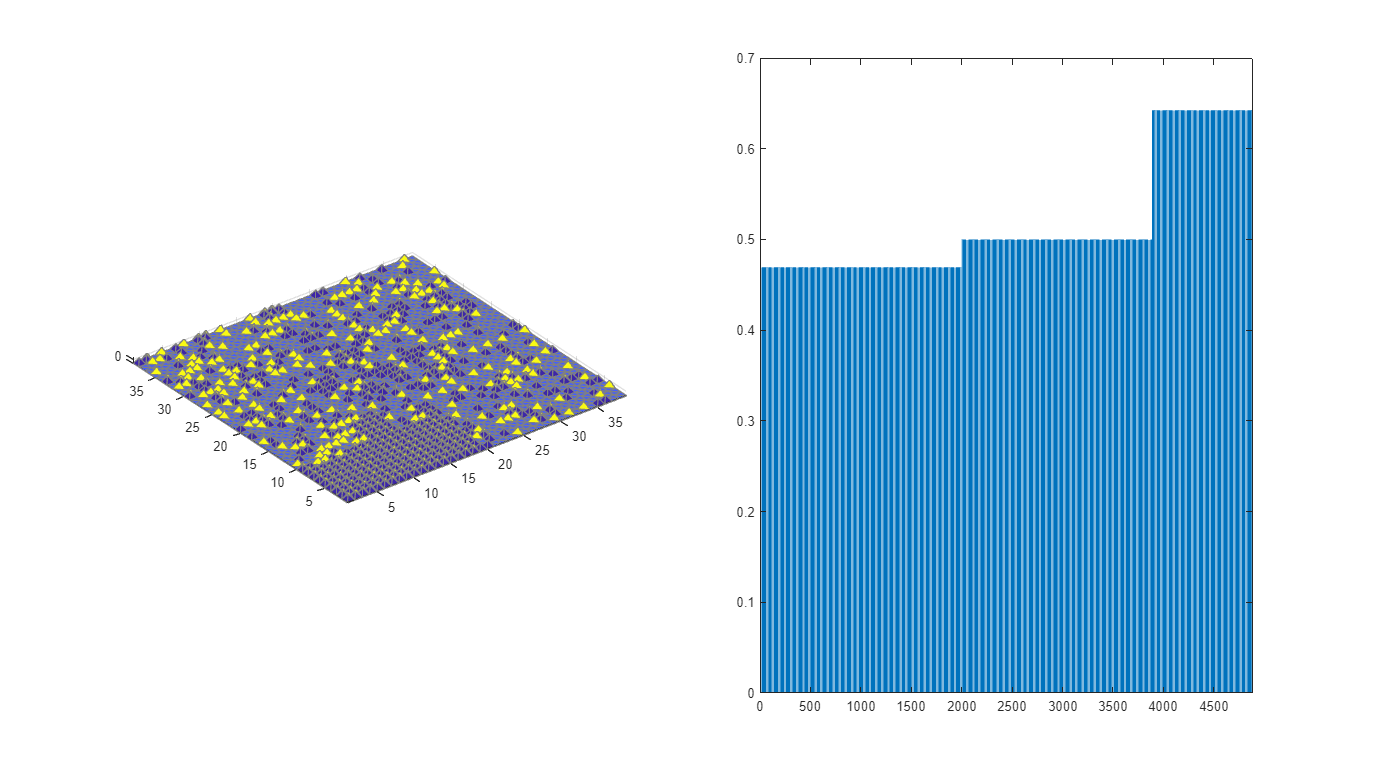

[v,f] = squareMesh3(39);
nf = height(f);
[v,f] = augmentFace(v,f,1:1000);
figuremax(); 
nexttile; trimeshmg(v, f); ff(); 
nexttile; bar(sort(calcFaceArea(v,f)));